# Praktikum 1 - Shift 1 Selasa - Kunci Jawaban

`7 September 2021`

`Nama : ``Asisten Praktikum `

`NIM  :`

## Nomor 1

Jelaskan perbedaan mendasar antara *anonymous function* dengan fungsi biasa pada MATLAB !

**Jawaban : **

Fungsi anonymous dapat dibuat tanpa melalui program file yang terpisah (secara inline) sedangkan fungsi biasa pada MATLAB harus melalui program file yang terpisah. 

## Nomor 2

Buatlah *plot *sinusoidal seperti berikut. 

Amati, warnanya *alternating* merah-hijau-biru setiap kelipatan 0.1 di sumbu horizontal.

Pastikan nilai batas-batas sumbu horizontal sudah benar. Jadi, tentu $x$ bukan dari 0 sampai 2*pi.

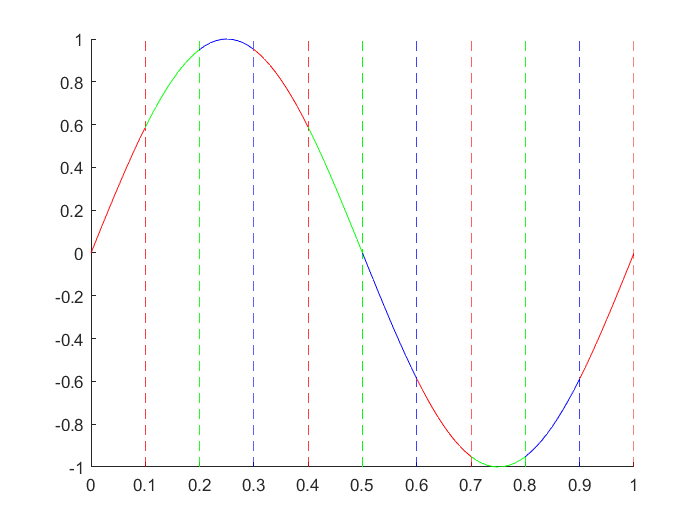

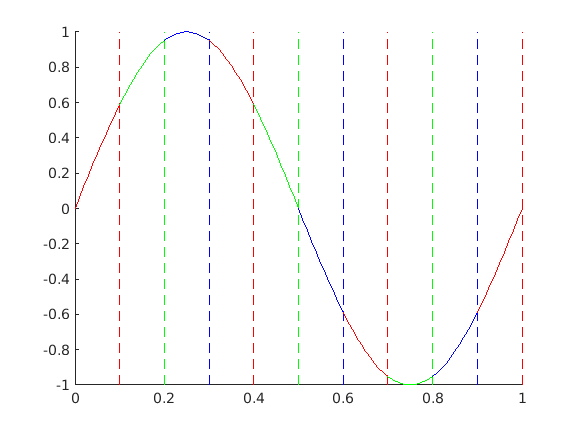

% Tulis jawaban anda dibawah garis
% --------------------------------
x = linspace(0, 1, 101);
y = sin(2*pi*x);
colors = ['r','g','b'];
figure
hold on
for i = 1:10
    startpos = 1 + 10*(i - 1);
    endpos = 1 + 10*i;
    plot(x(startpos:endpos), ...
        y(startpos:endpos), colors(mod(i-1, 3) + 1));
    plot(ones(100)*i/10, linspace(-1, 1),...
          strcat(colors(mod(i-1, 3) + 1), '--'))
end

**Tips** : 

1) Kita dapat memberikan style plot sebagai nilai dari sebuah variabel string/char

*Contoh: *

Akan menghasilkan plot berwarna merah.

2) Cari tahu bagaimana cara menggabungkan dua string/char di MATLAB.

## Nomor 3

Suatu vektor $X=\left\lbrack \begin{array}{ccccc}
x_1  & x_2  & x_3  & \cdots  & x_n 
\end{array}\right\rbrack$dikatakan **"Mantap" **apabila terdapat suatu $x_i$ dan $x_j \;$($\left.j\not= i\right)$pada $X$ sehingga $x_i =x_j^2$. 

*Contoh : *

- $X=\left\lbrack 1,4,2\right\rbrack$ adalah vektor Mantap, karena $2^2 =4$.

- $X=\left\lbrack 3,5,3,7\right\rbrack$ bukan vektor Mantap.

Vektor $X=\left\lbrack \begin{array}{ccccc}
x_1  & x_2  & x_3  & \cdots  & x_n 
\end{array}\right\rbrack$dikatakan **"Jiwa" **apabila terdapat suatu $x_i$ dan $x_j \;$($\left.j\not= i\right)$pada $X$ sehingga $x_i =x_j^3$.

*Contoh : *

- $X=\left\lbrack 2,9,8,7\right\rbrack$ adalah vektor Jiwa, karena $2^3 =8$.

- $X=\left\lbrack 1,4,5,3\right\rbrack$ bukan vektor Jiwa.

Apabila vektor $X$ adalah vektor **"Mantap"** dan **"Jiwa"** sekaligus, maka vektor tersebut disebut sebagai vektor **"Mantap Jiwa". **Vektor $X$ disebut vektor **"Biasa"** apabila tidak **"Mantap"** dan tidak **"Jiwa".**

Bangunlah sebuah fungsi di file berjudul `cekVektor.m` yang menerima masukan vektor/array $X$ dengan panjang $n$, dengan keluaran sebuah `string` yang menyatakan jenis vektor tersebut.

% Cek jawaban disini
x = [2,1,4,8,5,3];
jenis = cekVektor(x);
fprintf("Vektor ini adalah vektor berjenis : " + jenis)

Vektor ini adalah vektor berjenis : Mantap Jiwa